## Resistance

load resistance.mat

R = 1 / (V \ I)

R = 2.8156

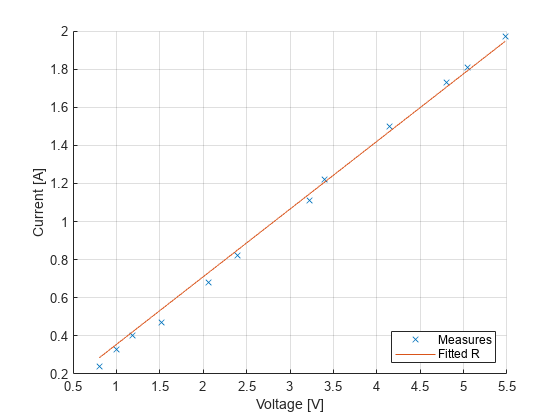


figure;
hold on; 
plot(V, I, 'x');
plot(V, V/R_regr);
legend("Measures", "Fitted R", 'location', 'southeast')
xlabel("Voltage [V]")
ylabel("Current [A]")
grid on;

## Inductance

L = 4.5e-3;

## Flux constant

load flux_constant.mat

kphi = 1/ ( (V - I*R) \ w )

kphi = 0.0333

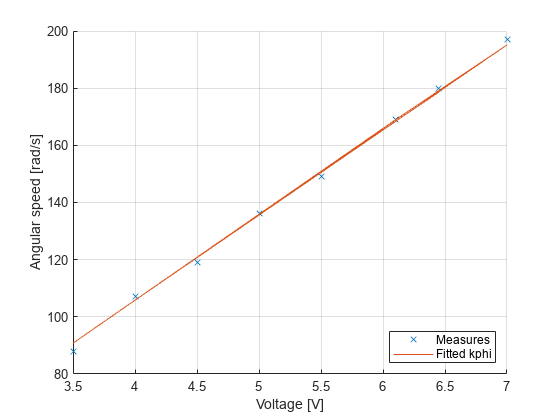


figure;
hold on;
plot(V, w, 'x');
plot(V, (V-R*I)/kphi );
legend("Measures", "Fitted kphi", 'location', 'southeast')
xlabel("Voltage [V]")
ylabel("Angular speed [rad/s]")
grid on;

## Rotor inertia - a occhio

% Positive step
load step.mat

y_ss = mean(y( length(y)/2:length(y))); % Steady state
y_ss_63 = 0.63 * y_ss;                  % 63% of steady state

figure;
hold on;
plot(t,y);
yline(y_ss, '--');
yline(y_ss_63, ':');
grid on;

Tm1_positive = 1.057 - 1

Tm1_positive = 0.0570

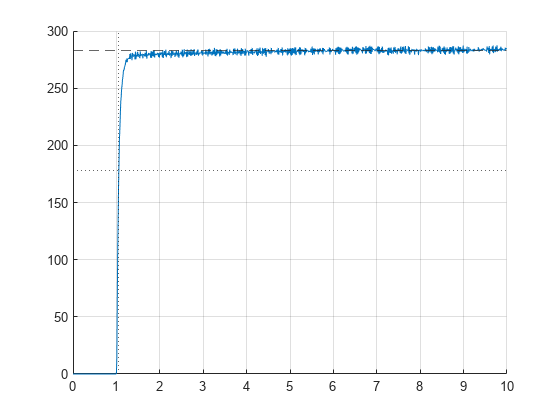

xline(Tm1_positive + 1, ':')


% Negative step
load step_negative.mat

y_ss = mean(y( length(y)/2:length(y))); % Steady state
y_ss_63 = 0.63 * y_ss;                  % 63% of steady state

figure;
hold on;
plot(t,y);
yline(y_ss, '--');
yline(y_ss_63, ':');
grid on;

Tm1_negative = 1.059 - 1

Tm1_negative = 0.0590

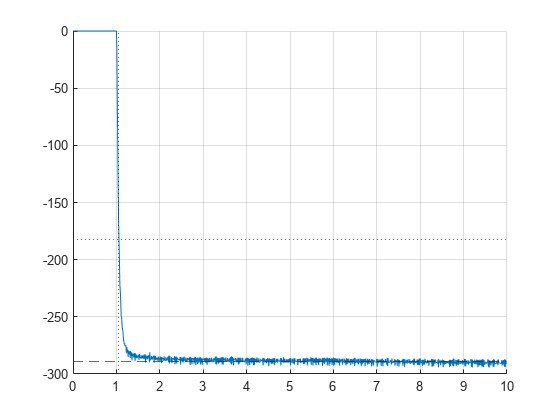

xline(Tm1_negative + 1, ':')


% Mean between positive and negative
Tm1 = mean([Tm1_positive, Tm1_negative]);

% Inertia
J_rot = kphi^2 * Tm1 / R

J_rot = 2.2809e-05

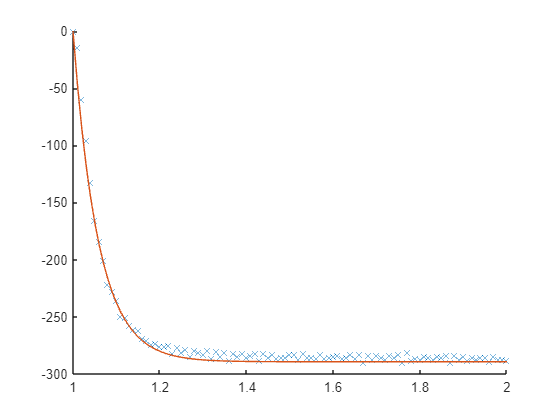



prediction = y_ss * (1 - exp(-t/Tm1));
prediction = [ zeros(1/Ts,1); prediction(1 : length(prediction)-1/Ts)];

figure;
hold on;
plot(t,y, 'x');
plot(t, prediction )
xlim([1,2])

## Rotor inertia - regression

### Positive step

load step.mat

y_ss = mean( y( length(y)/2 : length(y) ) ); % Steady state

% Preprocess: isolate the rising edge and normalize
Ts = t(2) - t(1);
t_lowerbound = 1.02;
t_upperbound = 1.1;
t_cut = t( (t_lowerbound/Ts)+1 : (t_upperbound/Ts)+1 ) - 1;
y_cut = y( (t_lowerbound/Ts)+1 : (t_upperbound/Ts)+1 ) / y_ss;

% Linearize the rising edge with the logarithm and fit the time
% constant
log_y_diff = log(1 - y_cut);
Tm1_positive = - log_y_diff \ t_cut

Tm1_positive = 0.0560

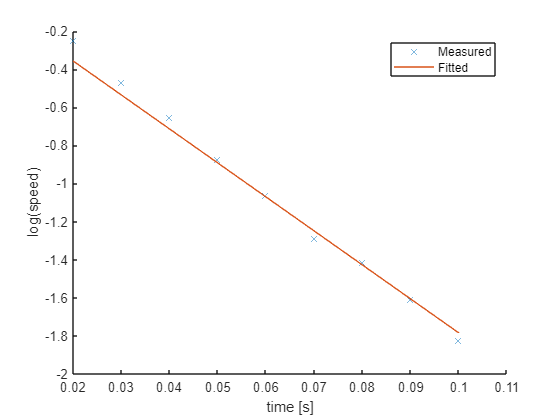


figure; hold on;
plot(t_cut, log_y_diff, 'x');
plot(t_cut, -1/Tm1_positive*t_cut)
xlabel("time [s]")
ylabel('log(speed)')
legend("Measured", "Fitted");

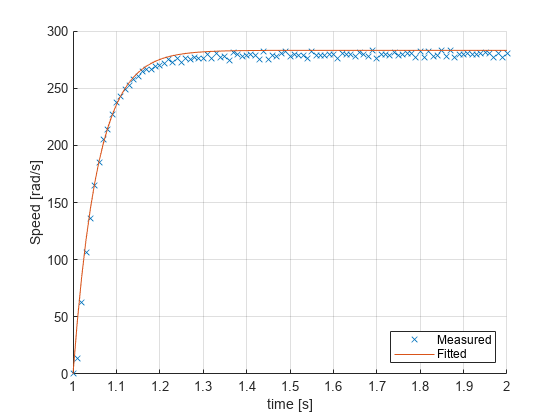


% Compare with the measurements
prediction = y_ss * (1 - exp(-t/Tm1_positive));
prediction = [ zeros(1/Ts,1); prediction(1 : length(prediction)-1/Ts)];

figure; hold on;
plot(t, y, 'x');
plot(t, prediction);
xlim([1,2])
xlabel('time [s]')
ylabel("Speed [rad/s]")
legend("Measured", "Fitted", 'location', 'southeast');
grid on;

### Negative step

load step_negative.mat

y_ss = mean( y( length(y)/2 : length(y) ) ); % Steady state

% Preprocess: isolate the rising edge and normalize
Ts = t(2) - t(1);
t_lowerbound = 1.02;
t_upperbound = 1.1;
t_cut = t( (t_lowerbound/Ts)+1 : (t_upperbound/Ts)+1 ) - 1;
y_cut = y( (t_lowerbound/Ts)+1 : (t_upperbound/Ts)+1 ) / y_ss;

% Linearize the rising edge with the logarithm and fit the time
% constant
log_y_diff = log(1 - y_cut);
Tm1_negative = - log_y_diff \ t_cut

Tm1_negative = 0.0588

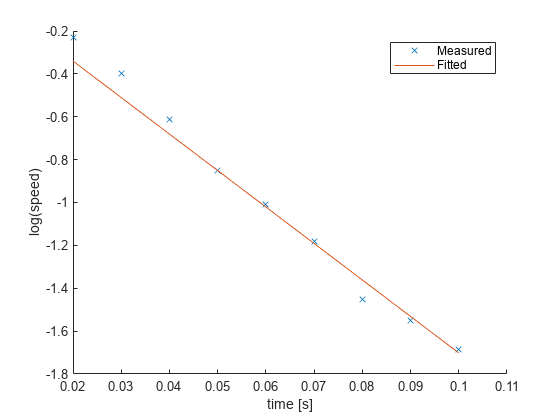


figure; hold on;
plot(t_cut, log_y_diff, 'x');
plot(t_cut, -1/Tm1_negative*t_cut)
xlabel("time [s]")
ylabel('log(speed)')
legend("Measured", "Fitted");

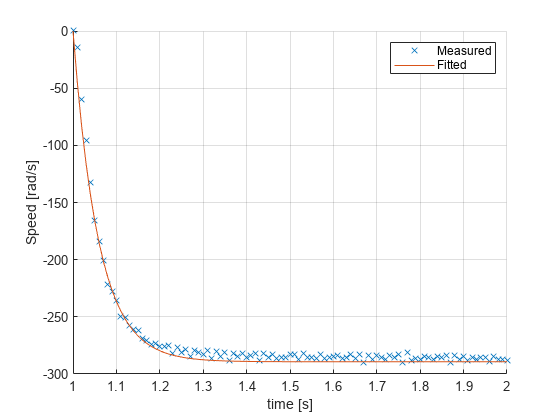


% Compare with the measurements
prediction = y_ss * (1 - exp(-t/Tm1_negative));
prediction = [ zeros(1/Ts,1); prediction(1 : length(prediction)-1/Ts)];

figure; hold on;
plot(t, y, 'x');
plot(t, prediction);
xlim([1,2])
xlabel('time [s]')
ylabel("Speed [rad/s]")
legend("Measured", "Fitted");
grid on;

### Mean

Tm1 = mean([Tm1_positive, Tm1_negative])

Tm1 = 0.0574


% Inertia
J_rot = kphi^2 * Tm1 / R

J_rot = 2.2574e-05

## Save the data

save("parameters.mat", "R", "L", "kphi", "J_rot")